# Revisão de SisDin 1

### Algumas formulas de sistema de segunda ordem


$$\sigma=\zeta\omega_n$$



$$\omega_d=\omega_n\sqrt{1-\zeta^2}$$



$$\beta=acos(\zeta)$$



$$t_p=\frac{\pi}{\omega_d}$$



$$t_r=\frac{\pi-\beta}{\omega_n\sqrt{1-\zeta^2}}$$



$$t_s^{2\%}=\frac{4}{\sigma}$$



$$$M_p=exp(\frac{-\pi\zeta}{\sqrt{1-\zeta^2}})$$$



$$\zeta=\frac{|ln( M_p)|}{\sqrt{\pi^2+ln^2(M_p)}}$$



$$MF=100\zeta º$$



$$s=-\zeta\omega_n\pm j\omega_n\sqrt{1-\zeta^2}$$


Erro ao degrau


$$K_p=\lim_{s\rightarrow0}G(s)$$



$$e(\infty)=\frac{1}{1+K_p}$$


Erro à rampa


$$K_v=\lim_{s\rightarrow0}sG(s)$$



$$e(\infty)=\frac{1}{K_v}$$


### Critério de estabilidade de routh-hurwitz

Exemplo:


$$FTMF=\frac{K(s+2)}{s^4+4s^3+9s^2+(10+K)s+2K}$$


montamos a tabela:


$$\begin{array}{cccc} s^4&1&9&2K\\s^3&4&(10+K)\\s^2&\frac{26-K}{4}&\frac{8K}{4}\\s^1&\frac{\frac{26-K}{4}(1+k)-8K}{\frac{26-K}{4}}=A\\s^0&\frac{A\frac{8K}{4}}{A} \end{array}$$


O número de raízes de FTMF com parte real positiva é igual ao número de mudanças de sinal na primeira coluna. Logo, para estabilidade devemos fazer todos os elementos da primeira coluna maiores que zero, além de fazer todos os elementos das 2 primeiras linhas maiores que zero também.

# Diagramas de resposta em frequência

## Diagrama de Bode

É a resposta em freqência de um sistema a uma entrada senoidal. Não precisa saber fazer, (função bode(sys) do matlab ou python), mas caso caia alguma questão mais teórica é bom ter ideia do que representa cada coisa nele.

### 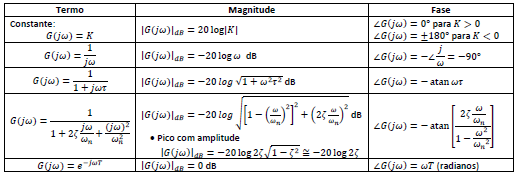

## Diagrama de Nyquist

Gráfico polar da resposta em freqência. O comprimento de uma reta que vai da origem a um ponto da curva representa $|G(j\omega)|$para uma determinada frequência e o ângulo entre essa reta e o eixo real positivo representa $\angle{G(j\omega)}$.

Onde termina o diagrama?

Se o número de pólos é maior que o número de zeros em malha aberta ($n>m$), $|G(j\infty)|\rightarrow 0$.

100% dos casos dessa matéria $n>m$, então precisamos nos preocupar só com a fase $\angle{G(j\infty)}$ 

Se $n-m=1$, $\angle{G(j\infty)}\rightarrow -90º$

Se $n-m=2
$, $\angle{G(j\infty)}\rightarrow -180º$

Se $n-m=3
$, $\angle{G(j\infty)}\rightarrow -270º$

Onde começa o diagrama?

Depende do tipo $N$ da FT de malha aberta (quantos pólos ela tem em zero)

Se $N=0$, $|G(0)|=K_0$ e $\angle{G(0)}=0º$, sendo $K_0$ o ganho da FT de malha aberta.

Se $N=1$, $|G(0)|=\infty$ e $\angle{G(0)}=-90º$

Se $N=2$, $|G(0)|=\infty$ e $\angle{G(0)}=-180º$

Se $N=3$, $|G(0)|=\infty$ e $\angle{G(0)}=-270º$

### Teorema da estabilidade de Nyquist

Seja $Z$ o número de pólos no SPD em malha fechada, $P$ o número de pólos no SPD em malha aberta e $N$ o número de voltas no sentido horário que o diagrama de Nyquist dá em volta do ponto -1 do eixo real. Para que o sistema seja estável, $Z=0$. É possível provar que $Z=P+N$. Logo, para a estabilidade, $N=-P$.

## Diagrama (ou carta) de Nichols

Ele é bem chato de entender e o Tannuri falou que ele é pouco usado. Então, dificilmente ele vai cair. Porém vou escrever aqui o que entendi dele.

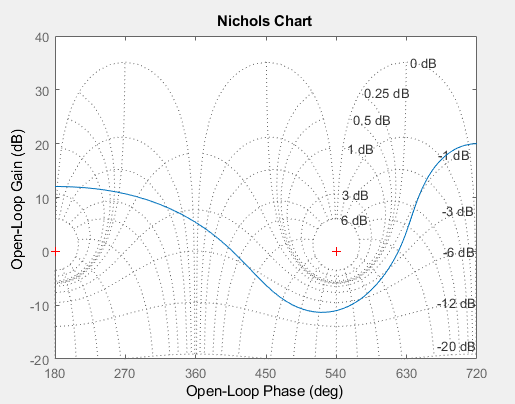

O eixo vertical é o ganho em malha aberta e o eixo horizontal é a fase em malha aberta. As linhas pontilhadas representam o ganho em malha fechada. Então, traçando a curva azul para a malha aberta, é possível ter uma noção do comportamento do sistema em malha fechada. É possível, por exemplo, construir o diagrama de bode de módulo em malha fechada pegando alguns pontos do diagrama de Nichols da FT de malha aberta.

# Margens

A **margem de ganho** é o inverso do módulo na frequência na qual a fase é -180º, ou seja, a parte imaginária do denominador de $G(j\omega)$ é nula. Ela é positiva se o ganho para essa frequência for menor que 1. Já a **margem de fase** é a distância entre a fase na frequência em que $|G(j\omega)|=1$ (ou $|G(j\omega)|_{dB}=0dB$) e -180º, ou seja, 180º mais essa fase. As duas margens são facilmente calculadas pelo comando margin(sys). Lembrar que esse comando calcula a  margem de ganho em db, ou seja, $MG_{dB}=20log_{10}(MG)$.

# Projeto em frequência de compensadores

## Compensador de avanço

$G_c=K_c\frac{1+sT}{1+\alpha sT}$, para $\alpha<1$. Recomendado para projeto onde são especificados o** erro em regime** e a **margem de fase** desejados. Se chama "de avanço" poruqe desloca a frequência de corte da margem de fase para a direita. 

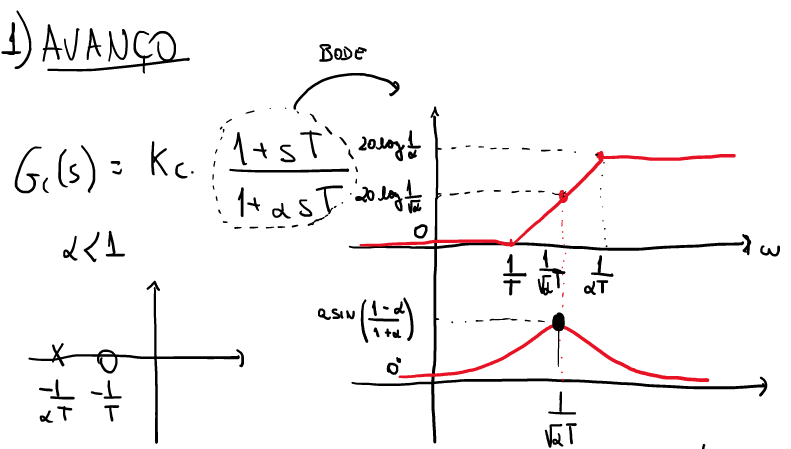

-  Obter o ganho $K_c$ para o erro estacionário desejado (ver as fórmulas de erro para entrada degrau e rampa)

- Obter a MF para o sistema não compensado $G_c=K_c$

- Obter o avanço necessário $\phi_m=MF_{desejada}-MF_{com ganho}+\Delta$, com $\Delta=5º \tilde\ 10º$

- Obter $\alpha=\frac{1-sin(\phi_m)}{1+sin(\phi_m)}$

- Obter a nova frequência de corte $\omega_c$ para a margem de fase, onde $|G(j\omega)|=-20log(\frac{1}{\sqrt{\alpha}})$

- Obter $T$ tal que $\omega_c=\frac{1}{\sqrt{\alpha}T} \rightarrow T=\frac{1}{\sqrt{\alpha}\omega_c}$

- Verificar com margin($G_cG$)

Kc=(1-0.05)/0.05 % mudar Kc
s=tf('s');
G=1/(s^2+s+1); % mudar a FT
[MG,MF]=margin(Kc*G)
phi=50-MF+10 % mudar a margem de fase
alfa=(1-sind(phi))/(1+sind(phi))
[mag,phase,wout] = bode(Kc*G);
modulo=-20*log10(1/sqrt(alfa))
wc=interp1(20*log10(mag(:)),wout,modulo)
T=1/(sqrt(alfa)*wc)
Gc=Kc*(1+T*s)/(1+T*s*alfa)
margin(G*Gc)
sys=feedback(G*Gc,1);
t=linspace(0,50,100);
y=step(sys/s,t);
r=step(1/s,t);
erro=(r(end)-y(end))
Kv=1/erro

## Compensador de atraso

$G_c=K_c\frac{1+sT}{1+\beta sT}$, para $\beta>1$. Aumenta a margem de fase e atenua o ganho em alta frequência. Recomendado para projeto onde são especificados o** erro em regime** e a **margem de fase** desejados. Se chama "de atraso" porque desloca a frequência de corte da margem de fase para a esquerda. 

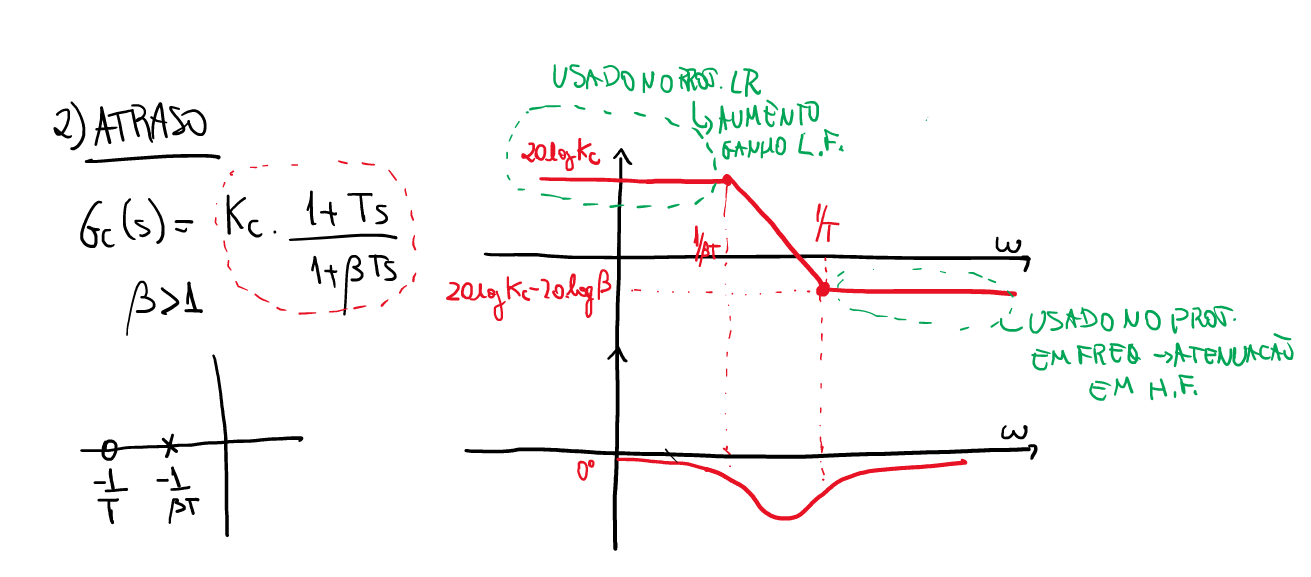 

-  Obter o ganho $K_c$ para o erro estacionário desejado (ver as fórmulas de erro para entrada degrau e rampa)

- Obter a MF para o sistema não compensado $G_c=K_c$ e a frequência de corte $\omega_c$

- Obter a nova frequência de corte na qual a fase $\angle{G(j\omega)}=-(180º-MF_{desejada})+\Delta$, com $\Delta=5º \tilde\ 10º$ 

- Obter o modulo do ganho na nova $\omega_c$. O compensador deve atenuar esse valor em alta frequência.

- Obter $\beta$ tal que $20log(\beta)=|G(j\omega_c^{nova})|\rightarrow\beta=10^{\frac{|G(j\omega_c^{nova})|}{20}}$

- Obter $T$ tal que $\frac{1}{T}\leq\frac{\omega_c^{nova}}{10}\rightarrow T=\frac{10}{\omega_c^{nova}}$

- Verificar com margin($G_cG$)

s=tf('s');
G=0.5/(s*(0.1*s+1)*(0.001*s+0.01)); % mudar a FT
Kv=1/0.03
Kc=Kv/0.5*0.01 % mudar Kc
[Gm,Pm,Wcg,Wcp] = margin(Kc*G)
fase=-(180-35)+10 %mudar a margem de fase
[mag,phase,wout] = bode(Kc*G);
wc=interp1(phase(:),wout,fase)
modulo=interp1(wout,20*log10(mag(:)),wc)
beta=10^(modulo/20)
T=10/wc
Gc=Kc*(1+s*T)/(1+s*beta*T)
margin(G*Gc)
t=linspace(0,50,100);
sys=feedback(Gc*G,1);
y=step(sys/s,t);
r=step(1/s,t);
erro=(r(end)-y(end))
Kv=1/erro

# Controle de Espaço de Estados

## Forma de espaço de estados

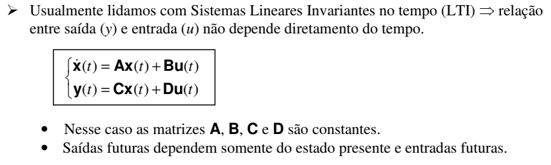

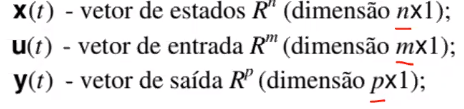

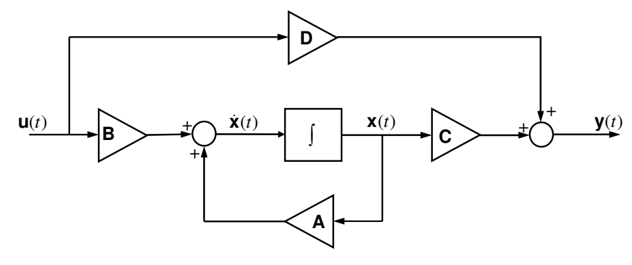

A matriz A é sempre quadrada e suas dimensões representam a ordem do sistema dinâmico. Além disso, os autovalores de A representam os pólos do sistema.

A FT tbm pode ser calculada pelo comando ss2tf(sys) 

## Controlabilidade e Observabilidade

**Controlabilidade **é a capacidade de se levar um sistema para qualquer estado $x$ em um tempo t. É medido pelo rank da matriz gerada pelo comando $M_c=ctrb(A,B)$. $rank(M_c)=n$, sendo $n$ a ordem do sistema. 

**Observabilidade **é a capacidade de se saber qualquer estado $x$ conhecendo a saída $y$ e a entrada $u$. É medido pelo rank da matriz gerada pelo comando $M_o=obsv(A,C)$. $rank(M_o)=n$, sendo $n$ a ordem do sistema. 

Mo=obsv(A,C);
Mc=ctrb(A,B);
rank(Mo)
rank(Mc)

## Alocação de polos

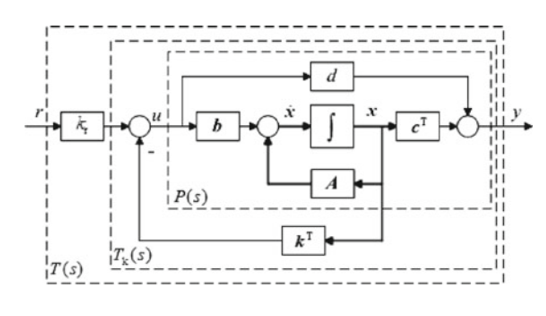

- Verificar a observabilidade e a controlabilidade

- Encontrar os pólos desejados pelos requisitos de controle e escrevelos em um vetor $p_k$. O vetor precisa ter como comprimento a ordem do sistema. Caso ele precise de mais pólos além dos desejados, fazer com que sejam grandes o suficiente para serem não dominantes.

- calcular a matriz $K=place(A,B,p_k)$

- Fazer $K_r=1$ e calcular as matrizes de malha fechada $A_{MF}=A-BK$, $B_{MF}=BK_r$, $C_{MF}=C-DK$e $D_{MF}=DK_r$

- Declarar o sistema de malha fechada usando o comando $sys=ss(A_{MF},B_{MF},C_{MF},D_{MF})$

- Calcular $K_r=1/dcgain(sys)$

- Recalcular as matrizes de malha fechada e o sistema para o novo $K_r$

- Simular para testar

clear;clc;close all;
A=[0.5,1;1,0]; % mudar matriz
B=[1;0]; % mudar matriz
C=[0,1]; % mudar matriz
D=0; % mudar matriz
n=length(A)
Mo=obsv(A,C);
Mc=ctrb(A,B);
rank(Mo)==n
rank(Mc)==n
pk=[-0.3;-0.7]; % polos desejados
K=place(A,B,pk)
Kr=1;
Amf=A-B*K;
Bmf=B*Kr;
Cmf=C-D*K;
Dmf=D*Kr;
sys_mf=ss(Amf,Bmf,Cmf,Dmf);
step(sys_mf)
Kr=1/dcgain(sys_mf)
Amf=A-B*K;
Bmf=B*Kr;
Cmf=C-D*K;
Dmf=D*Kr;
sys_mf=ss(Amf,Bmf,Cmf,Dmf);
step(sys_mf)
damp(sys_mf)

## Controle ótimo

Tem como objetivo minimizar o funcional $J_{\infty}(t)=\int_t^\infty[X^T(\tau)Q(\tau)X(\tau)+u^T(\tau)R(\tau)u(\tau)]d\tau$ , no qual a primeira parcela representa a precisão que queremos controlar as variáveis de estado e a segunda parcela representa a energia gasta pelo controlador. Fazemos isso calculando a matriz de controle $K$ usando como parâmetro as matrizes $Q_{nxn}$ e $R_{mxm}$, sendo $n$ o número de variáveis de estado e $m$ o número de entradas. A matriz $Q$ representa em sua diagonal a importância da precisão do controle para cada variável de estado e a matriz $R$ o quanto de energia desejamos gastar.

- Verificar a observabilidade e a controlabilidade

- Escrever o sistema de malha aberta $sys=ss(A,B,C,D)$

- Escrever a matriz $Q$ colocando na diagonal dela a importância que vc quer dar para a precisão do controle de cada variável de estado.

- Escrever a matriz $R=P^2$, sendo $P$ um parâmetro que vc irá variar para verificar se o gasto de energia está satisfatório. (Nesse caso consideramos um sistema com apenas uma entrada. O Tannuri não ensinou como seria para mais de uma entrada, mas provavelmente R seria uma matriz diagonal e seria possível dar pesos diferentes para cada entrada, assim como fazemos com os estados na matriz $Q$)

- Calcular $K$ usando $[K,S,e] = lqr(sys,Q,R)$. ( 'S' e 'e' não são utilizados porém precisam estar no comando)

- Fazer $K_r=1$ e calcular as matrizes de malha fechada $A_{MF}=A-BK$, $B_{MF}=BK_r$, $C_{MF}=C-DK$e $D_{MF}=DK_r$

- Declarar o sistema de malha fechada usando o comando $sys=ss(A_{MF},B_{MF},C_{MF},D_{MF})$

- Calcular $K_r=1/dcgain(sys)$

- Recalcular as matrizes de malha fechada e o sistema para o novo $K_r$

- Simular para testar tanto a saída $y$ quanto a entrada $u=Kx^T+(rK_r)$, sendo r o setpoint. 

- Variar $Q$ e $R$ até $y$ e $u$ serem satisfatórios.

clear;close all;clc;
A=[0,1,0;980,0,-2.8;0, 0,-100]; % mudar a matriz
B=[0;0;100]; % mudar a matriz
C=[1,0,0]; % mudar a matriz
sys_ma=ss(A,B,C,0);
ct=rank(ctrb(A,B))
ob=rank(obsv(A,C))
P=0.1; % variar
R=P^2;
Q=[1,0,0;0,0.01,0;0,0,0.01]; % variar
[K,S,e] = lqr(sys_ma,Q,R);
K
Kr=1;
Amf=A-B*K;
Bmf=B*Kr;
sys_mf=ss(Amf,Bmf,C,0);
Kr=1/dcgain(sys_mf);
Bmf=B*Kr;
sys_mf=ss(Amf,Bmf,C,0);
t=linspace(0,0.4,50); % tempo da simulação
r=ones(1,length(t)); % entrada degrau
[y,t,x] = lsim(sys_mf,r,t);
plot(t,y)
title('Posição')
ylabel('h')
xlabel('t')
u=K*x'+(r*Kr);
plot(t,u)
title('Esforço de controle')
ylabel('tensão')
xlabel('t')

## Controle integral

É pareecido com o controle por alocação de pólos, porém no lugar de calcular um ganho $K_r$ você define uma nova variável de estado como a integral do erro $z=\int(y-y_d)dt$, onde $y_d$ é o setpoint.

$\dot z = y - y_d$ (erro)

O vetor de estados expandido fica $x_e=\left\{\begin{array}{c}        x \\     z \\    \end{array}\right\}$ e as matrizes de estado expandidas em malha aberta ficam $\dot x_e = \left\{\begin{array}{c}    \dot    x \\  \dot   z \\    \end{array}\right\} \left(\begin{array}{c c}  A_{nxn} & 0_{nx1} \\  C_{nx1} & 0    \end{array}\right)x_e+ \left\{\begin{array}{c}  B_{mxm} \\  0_{1xm} \end{array}\right\}u+\left\{\begin{array}{c}  0 \\  -y_d \end{array}\right\}=A_{int}x_e+B_{int}u+\left\{\begin{array}{c}  0 \\  -y_d \end{array}\right\}$

$y=\left\{\begin{array}{cc}  C &  0 \end{array}\right\}x_e=C_{int}x_e$ (vamos considerar D=0).

- Encontrar os pólos desejados pelos requisitos de controle e escrevelos em um vetor $p_k$

- Escrever as matrizes expandidas 

- Verificar a controlabilidade para as matrizes expandidas (lembrar de somar 1 na ordem, pois tem um estado a mais agora)

- Adicionar mais um pólo não dominante em $p_k$ para compatibilizar com as matrizes expandidas. 

- calcular a matriz $K=place(A_{int},B_{int},p_k)$

- escrever as matrizes de malha fechada $A_{mf}=A_{int}-B_{int}K$, $B_{MF}=\left\{\begin{array}{c}  0_{nx1} \\  -1 \end{array}\right\}$ e $C_{MF}=\left\{\begin{array}{cc}  C &  0 \end{array}\right\}$

- Declarar o sistema de malha fechada usando o comando $sys=ss(A_{MF},B_{MF},C_{MF},0)$

- Simular

clear;close all;clc;
A=[0,1,0;980, 0,-2.8;0, 0,-100]; % mudar a matriz
B=[0;0;100]; % mudar a matriz
C=[1,0,0]; % mudar a matriz
D=0; % mudar a matriz
n=length(A)
pk=[-50,-10+10j,-10-10j]; % mudar os pólos
Aint=[A,zeros(n,1);C,0];
Bint=[B;0];
Cint=[C,0];
rank(obsv(Aint,Cint))==n
p(n+1)=-60; % adicionando mais um polo não dominante por causa da nova variável de estado
K=place(Aint,Bint,pk)
Amf=Aint-Bint*K;
Bmf=[zeros(n,1);-1];
Cmf=Cint;
nt=1000;
t=linspace(0,2,nt);
yd=0.01*ones(nt,1); % degrau de 0.01
sys=ss(Amf,Bmf,Cmf,0);
lsim(sys,yd,t)

## Observador de estados

Serve para estimar os estados de um sistema de controle.

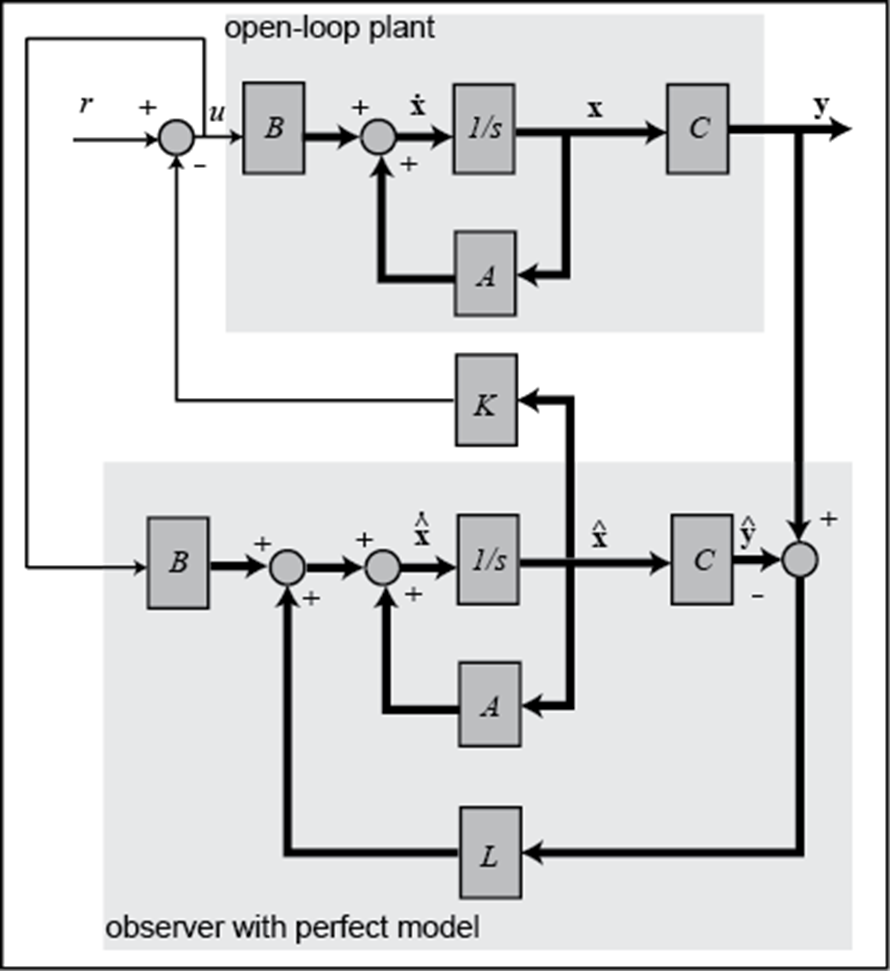


$$x_e=\left\{\begin{array}{c}        x \\     \hat  x \\    \end{array}\right\}$$



$$\dot x_e = \left(\begin{array}{c c}  A & -BK \\  LC & A-BK-LC    \end{array}\right)x_e+ \left\{\begin{array}{c}  BK_r \\  BK_r   \end{array}\right\}r=A_{obs}x_e+B_{obs}r$$



$$y_e=\left\{\begin{array}{c}        y \\     \hat  y \\    \end{array}\right\}= \left(\begin{array}{c c}  C & 0 \\  0 & C    \end{array}\right)+Dr= C_{obs}x_e+Dr$$


- Definir os polos do observador ($p_{obs}$) 5x maiores que os do sistema

- Calcular $L=place(A^T,C^T,p_{obs})^T$

- Fazer $K_r=1$ e calcular as matrizes expandidas $A_{obs}$, $B_{obs}$, $C_{obs}$, $D_{obs}$.

- Delcarar o sistema $obsys=ss(A_{obs},B_{obs},C_{obs},D_{obs})$

- Calcular $K_r=1/dcgain(obsys)$

- Recalcular as matrizes de malha fechada e o sistema para o novo $K_r$

- Simular para testar

clear;close all;clc;
A=[0,1,0;980, 0,-2.8;0, 0,-100]; % mudar a matriz
B=[0;0;100]; % mudar a matriz
C=[1,0,0]; % mudar a matriz
D=0; % mudar a matriz
pk=[-10;-11;-12;-13]; %m udar os pólos
K=place(A,B,pk)
Kr=1;
sys_mf=ss(A-B*K,B*Kr,C,0)
Kr=1/dcgain(sys_mf)
sys_mf=ss(A-B*K,B*Kr,C-D*K,D*Kr);
nt=1000;
t=linspace(0,2,nt);
r=zeros(1,nt);
r(1,:)=1;
[y,t,x] = lsim(sys_mf,r,t);
plot(t,y(:,1));
xlabel("t(s)")
ylabel("x(m)")
title("Resposta a um degrau")
legend('y',"Location","best")
p_obs=5*pk;
L=place(A',C',p_obs)'
Kr=1;
A_obs=[A,-B*K;L*C,A-B*K-L*C];
B_obs=[B*Kr;B*Kr];
C_obs=[C,zeros(size(C));zeros(size(C)),C];
D_obs=0;
obsys=ss(A_obs,B_obs,C_obs,D_obs);
Kr=1/dcgain(obsys(1))
A_obs=[A,-B*K;L*C,A-B*K-L*C];
B_obs=[B*Kr;B*Kr];
C_obs=[C,zeros(size(C));zeros(size(C)),C];
D_obs=0;
obsys=ss(A_obs,B_obs,C_obs,D_obs);
x0=[1,0,-1,0,0,0,0,0]; % mudar as condiçòes iniciais
n=1000;
t = linspace(0,1,n);
R = zeros(n,1);
R(:) = 1;
[y,t,x] = lsim(obsys,R,t,x0);
% mudar os plots dependendo das variáveis de estado
subplot(2,2,1);
plot([t,t],[x(:,1),x(:,5)])
legend('real','estimado',"Location","best")
title('posição x_1')
subplot(2,2,2);
plot([t,t],[x(:,2),x(:,6)])
legend('real','estimado',"Location","best")
title('velocidade x_1')
subplot(2,2,3);
plot([t,t],[x(:,3),x(:,7)])
legend('real','estimado',"Location","best")
title('posição x_2')
subplot(2,2,4);
plot([t,t],[x(:,4),x(:,8)])
legend('real','estimado',"Location","best")
title('velocidade x_2')